# Practice NODC Cast work

% Load Data
cd('C:\Users\ajs82292\Desktop\Research\Matlab\Source')
load("02cleanNODC.mat")

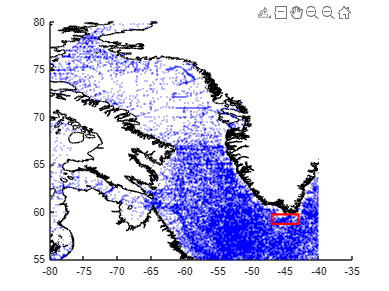

% Map
clf
hold on
plot(cx,cy,'k')
xlim([-80,-35])
ylim([55,80])
scatter(lon,lat,1,'MarkerFaceColor','b','MarkerEdgeAlpha','0') ;
rectangle('Position',[-47,58.7,4,1],'EdgeColor','red','LineWidth',2)
hold off

%Limit NODC Data to Square only to make interpolation easier
Squarelonindicies = (lon >= -47) & (lon <=-43) ;
lon = lon(Squarelonindicies) ;
lat = lat(Squarelonindicies) ;
sal = sal(Squarelonindicies) ;
temp = temp(Squarelonindicies) ;
mon = mon(Squarelonindicies);
day = day(Squarelonindicies);
yea = yea(Squarelonindicies);
watdep = watdep(Squarelonindicies);
dep = dep(Squarelonindicies) ;
% Lat
Squarelatindicies = (lat >= 58.7) & (lat <=59.7) ;
lon = lon(Squarelatindicies) ;
lat = lat(Squarelatindicies) ;
sal = sal(Squarelatindicies) ;
temp = temp(Squarelatindicies) ;
mon = mon(Squarelatindicies) ;
day = day(Squarelatindicies);
yea = yea(Squarelatindicies);
watdep = watdep(Squarelatindicies) ;
dep = dep(Squarelatindicies) ;

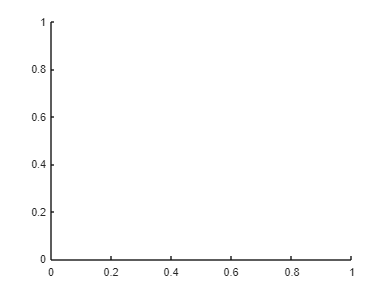

%Map New Restricted Data
clf
hold on
plot(cx,cy,'k')
xlim([-80,-35])
ylim([55,80])
scatter(lon,lat,2,'MarkerFaceColor','b','MarkerEdgeAlpha','0') ;
rectangle('Position',[-47,58.7,4,1],'EdgeColor','red','LineWidth',2)
hold off

%Interpolate every 1 m 
max_length = max(cellfun(@numel,dep)) ;
DepInterval = (0:1:max_length)';
int_temp = {} ;
for i = 1:1:length(dep)
    int_temp{1,i} = interp1(dep{1,i},temp{1,i}, DepInterval, 'linear') ;
end
%Salinity 
int_sal = {} ;
for i = 1:1:length(dep)
    int_sal{1,i} = interp1(dep{1,i},sal{1,i}, DepInterval, 'linear') ;
end

% Set Up Month Matrices
Julyindex = (mon == 7);
Augindex = (mon == 8);
Septindex = (mon == 9);
Octindex = (mon == 10);
JulyT = int_temp(Julyindex) ;
AugT = int_temp(Augindex) ;
SeptT = int_temp(Septindex) ;
OctT = int_temp(Octindex) ;
JulyS = int_sal(Julyindex) ;
AugS = int_sal(Augindex) ;
SeptS = int_sal(Septindex) ;
OctS = int_sal(Octindex) ;
% Matrices for Calculations
JulyT = cell2mat(JulyT);
AugT = cell2mat(AugT);
SeptT = cell2mat(SeptT);
OctT = cell2mat(OctT);
JulyS = cell2mat(JulyS);
AugS = cell2mat(AugS);
SeptS = cell2mat(SeptS);
OctS = cell2mat(OctS);

% Computations
%Averages
JulyTM = mean(JulyT, 2, 'omitnan') ;
AugTM = mean(AugT, 2, 'omitnan') ;
SeptTM = mean(SeptT, 2, 'omitnan') ;
OctTM = mean(OctT, 2, 'omitnan') ;
JulySM = mean(JulyS, 2, 'omitnan') ;
AugSM = mean(AugS, 2, 'omitnan') ;
SeptSM = mean(SeptS, 2, 'omitnan') ;
OctSM = mean(OctS, 2, 'omitnan') ;
% Standard Deviations
JulyTStd = std(JulyT, 0, 2, 'omitnan') ;
AugTStd = std(AugT, 0, 2, 'omitnan') ;
SeptTStd = std(SeptT, 0, 2, 'omitnan') ;
OctTStd = std(OctT, 0, 2, 'omitnan') ;
JulySStd = std(JulyS, 0, 2, 'omitnan');
AugSStd = std(AugS, 0, 2, 'omitnan');
SeptSStd = std(SeptS, 0, 2, 'omitnan');
OctSStd = std(OctS, 0, 2, 'omitnan');

% Subtract Each Cast by monthly Average for Anomaly
JulyTA = JulyT - JulyTM ;
JulySA = JulyS - JulySM ;
AugTA = AugT - AugTM ;
AugSA = AugS - AugSM ;
SeptTA = SeptT - SeptTM ;
SeptSA = SeptS - SeptSM ;
OctTA = OctT - OctTM ;
OctSA = OctS - OctSM ;

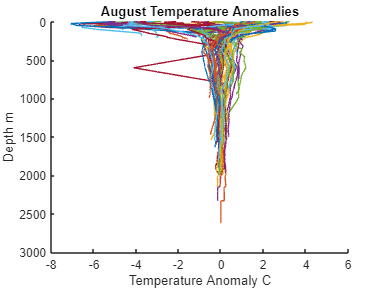

%August TA
clf
hold on
plot(AugTA,DepInterval)
title('August Temperature Anomalies')
xlabel('Temperature Anomaly C')
ylabel('Depth m')
axis ij
hold off

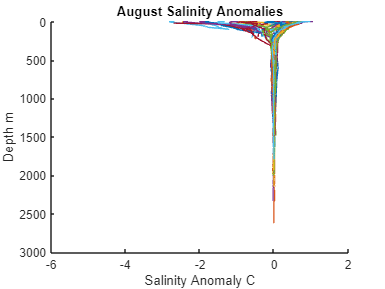

%August Salinity Anmoaly
clf
hold on
plot(AugSA,DepInterval)
title('August Salinity Anomalies')
xlabel('Salinity Anomaly C')
ylabel('Depth m')
axis ij
hold off

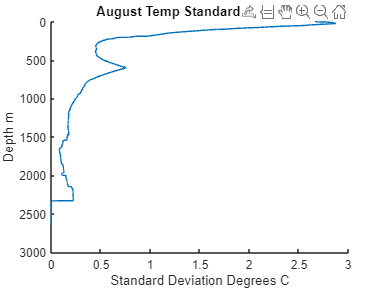

% August Temperature Std
clf
hold on
plot(AugTStd,DepInterval)
title('August Temp Standard Deviation')
xlabel('Standard Deviation Degrees C')
ylabel('Depth m')
axis ij
hold off

% August Salinity Std
clf
hold on

plot(AugSStd,DepInterval)

Unrecognized function or variable 'AugSStd'.

title('August Sal Standard Deviation')
xlabel('Standard Deviation Sal')
ylabel('Depth m')
axis ij
hold off

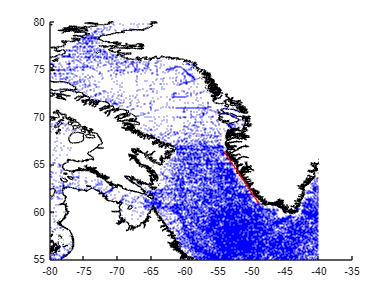

% Work on simplified coastline (ginput) (Needs to have better coast
% selection)
clf
hold on
plot(cx,cy,'k')
xlim([-80,-35])
ylim([55,80])
% Already selected coastline points
run = 2 ;
for i = 1:1:1
    if run == i 
        SWgcoast = ginput(2);
        save ("SWgcoast.mat", "SWgcoast");
    end
end
load('SWgcoast.mat')
scatter(lon,lat,1,'MarkerFaceColor','b','MarkerEdgeAlpha','0') ;
plot (SWgcoast(:,1),SWgcoast(:,2) ,'r')
hold off

% Creation of Rectangles on Coast (length is wrong, length of the side needs to be 20 not the interval)
clf
m = ((SWgcoast(2,2)-SWgcoast(1,2))/(SWgcoast(2,1)-SWgcoast(1,1))) %slope of simplified coastline

m = -1.0475

b = SWgcoast(1,2)-m*SWgcoast(1,1) ; % y intercept of coastline
m_perpindicular = -1/m

m_perpindicular = 0.9546

width = 10 ; % km
length = 20 ; % km
y_SWcoast = SWgcoast(2,2) - SWgcoast(1,2) ; % difference between y points
x_SWcoast = SWgcoast(2,1)- SWgcoast(1,1) ; % difference between x points
anglerectangles = atan2d(y_SWcoast,x_SWcoast) ; % degrees
angle_recd = deg2rad(anglerectangles) ;
SWlength = distance(SWgcoast(1,2),SWgcoast(1,1),SWgcoast(2,2),SWgcoast(2,1)) ; % degrees upscaling will be a pain
SWlengthkm = deg2km(SWlength) ; % km
lengthdeg = km2deg(length) ;
num_rectangles = floor(SWlengthkm / width);
y_km_interval = 14.449837 ; % calculated on paper, need to do the math here for repoducibillity (also not correct)      
y_deg_interval = km2deg(y_km_interval) ;
y_intervals = SWgcoast(2,2):-y_deg_interval:SWgcoast(1,2)

y_intervals =    66.3338   66.2039   66.0739   65.9440   65.8140   65.6841   65.5541   65.4242   65.2942   65.1643   65.0343   64.9044   64.7744   64.6445   64.5145   64.3846   64.2546   64.1247   63.9947   63.8648   63.7348   63.6049   63.4749   63.3450   63.2150   63.0851   62.9551   62.8252   62.6952   62.5653   62.4353   62.3054   62.1754   62.0455   61.9155   61.7856   61.6556   61.5257   61.3957   61.2657   61.1358   61.0058   60.8759


widthdeg = 111.320*cosd(y_intervals)

widthdeg =    44.6847   44.9158   45.1467   45.3774   45.6078   45.8380   46.0680   46.2977   46.5272   46.7564   46.9854   47.2142   47.4427   47.6710   47.8990   48.1268   48.3544   48.5817   48.8087   49.0355   49.2620   49.4883   49.7144   49.9401   50.1657   50.3909   50.6159   50.8407   51.0651   51.2894   51.5133   51.7370   51.9604   52.1836   52.4065   52.6291   52.8514   53.0735   53.2953   53.5168   53.7381   53.9591   54.1798


widthdeg = width./widthdeg

widthdeg =     0.2238    0.2226    0.2215    0.2204    0.2193    0.2182    0.2171    0.2160    0.2149    0.2139    0.2128    0.2118    0.2108    0.2098    0.2088    0.2078    0.2068    0.2058    0.2049    0.2039    0.2030    0.2021    0.2011    0.2002    0.1993    0.1984    0.1976    0.1967    0.1958    0.1950    0.1941    0.1933    0.1925    0.1916    0.1908    0.1900    0.1892    0.1884    0.1876    0.1869    0.1861    0.1853    0.1846


zero_x = (y_intervals-b) / m

zero_x =   -54.1302  -54.0061  -53.8821  -53.7580  -53.6340  -53.5099  -53.3859  -53.2618  -53.1378  -53.0137  -52.8896  -52.7656  -52.6415  -52.5175  -52.3934  -52.2694  -52.1453  -52.0213  -51.8972  -51.7732  -51.6491  -51.5250  -51.4010  -51.2769  -51.1529  -51.0288  -50.9048  -50.7807  -50.6567  -50.5326  -50.4086  -50.2845  -50.1605  -50.0364  -49.9123  -49.7883  -49.6642  -49.5402  -49.4161  -49.2921  -49.1680  -49.0440  -48.9199


ten_x = zero_x - widthdeg

ten_x =   -54.3540  -54.2288  -54.1036  -53.9784  -53.8532  -53.7281  -53.6029  -53.4778  -53.3527  -53.2276  -53.1025  -52.9774  -52.8523  -52.7273  -52.6022  -52.4772  -52.3521  -52.2271  -52.1021  -51.9771  -51.8521  -51.7271  -51.6021  -51.4772  -51.3522  -51.2273  -51.1023  -50.9774  -50.8525  -50.7276  -50.6027  -50.4778  -50.3529  -50.2280  -50.1032  -49.9783  -49.8534  -49.7286  -49.6038  -49.4789  -49.3541  -49.2293  -49.1045


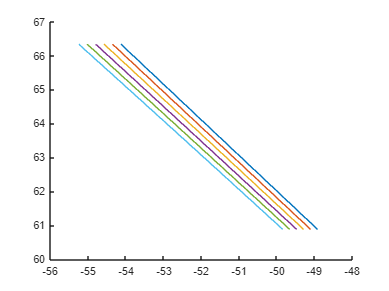

twenty_x = ten_x - widthdeg ;
thirty_x = twenty_x - widthdeg ;
fourty_x = thirty_x -widthdeg ;
fifty_x = fourty_x -widthdeg ;
hold on 
plot(zero_x,y_intervals)
plot(ten_x,y_intervals)
plot(twenty_x,y_intervals)
plot(thirty_x,y_intervals)
plot(fourty_x,y_intervals)
plot(fifty_x,y_intervals)
hold off

magnitude = sind(anglerectangles)*widthdeg

magnitude = 0.0651

ydeg = sqrt(magnitude^2-widthdeg^2)

ydeg = 0.0000 + 0.0621i

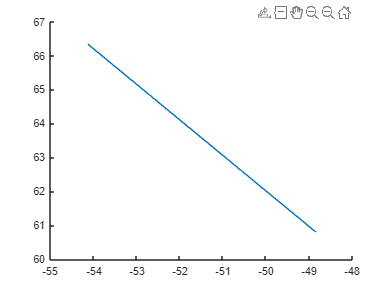

clf
hold on 
plot(SWgcoast(:,1),SWgcoast(:,2))

% Find nearest cx,cy and distance (need to fix shouldn't be linear)
coastlinepoints = [cx,cy] ;
lonlat = [lon',lat'] ;
idx_nearest = knnsearch(coastlinepoints, lonlat);
closest_cx = cx(idx_nearest);
closest_cy = cy(idx_nearest);
distances = sqrt((lon'-closest_cx).^2 +(lat'-closest_cy).^2) ; % ' to translate lat lon
d_lat = lat' - closest_cy ; 
d_lon = lon' - closest_cx ;
angles = atan2d(d_lat,d_lon) ;
angles = mod(angles, 360);
rads = deg2rad(angles) ;

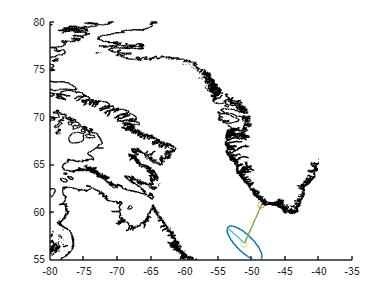

% Creation of angled ovals
clf
hold on
testx = [closest_cx(1,1),lon(1,1)] ;
testy = [closest_cy(1,1),lat(1,1)] ;
testx2 = [-53.5712,lon(1,1)] ;
testy2 = [58.2901,lat(1,1)] ;
tilt_angle = pi/2 ;
a = 3 ;
b = 1 ;
theta = linspace(0, 2*pi, 100) ; % Angles from 0-2pi
center = [lon(1,1), lat(1,1)] ;
x = center(1) + a * cos(theta) ;
y = center(2) + b * sin(theta) ;
x = x - lon(1,1) ;
y = y - lat(1,1) ;
R = [cos(rads(1,1)+tilt_angle), -sin(rads(1,1)+tilt_angle); sin(rads(1,1)+tilt_angle), cos(rads(1,1)+tilt_angle)];
rotated_coords = R * [x ; y] ;
x = rotated_coords(1, :) ;
y = rotated_coords(2, :) ;
x = x + lon(1,1) ;
y = y + lat(1,1) ;
plot(x,y)
scatter(closest_cx(1,1),closest_cy(1,1))
scatter(lon(1,1),lat(1,1))
plot(cx,cy, 'k')
xlim([-80,-35])
ylim([55,80])
plot(testx,testy)
plot(testx2,testy2)
hold off

% Major axis of ellipse
a_km = 7.5 ; % distance of major axis (this will change with distance from coastline)
lat1 = deg2rad(lat) ;
lon1 = deg2rad(lon) ;
bearing = rads ; % in radians
bearing = bearing' ;
R = 6371 ; % r of earth
d = a_km/R ; % Distance to Radians
lat2 = asin(sin(lat1) .* cos(d) + cos(lat1) .* sin(d) .* cos(bearing)) ;
lon2 = lon1 + atan2(real(sin(bearing) .* sin(d) .* cos(lat1)), real(cos(d) - sin(lat1) .* sin(lat2)));
lat2 = rad2deg(lat2) ;
lon2 = rad2deg(lon2) ;
latdiff = abs(lat2-lat) ; % degrees - degrees
londiff = abs(lon2-lon) ;
Amagnitudedistance = sqrt(latdiff.^2+londiff.^2) ;
%Minor Axis of Elipse (scaled to a)
asource = Amagnitudedistance ;
distances = sqrt((lon'-closest_cx).^2 +(lat'-closest_cy).^2) ;
equalization = 2.5 ; % distance at which a = b and becomes a circle
scaleb = min(1,distances/equalization) ;
scaleb = scaleb' ;
bsource =  min(asource,asource.*scaleb) ;

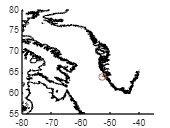

% Test, ensure B is never larger than a or the angle won't match
clf
hold on
indiv = 44 ;
tilt_angle = pi/2 ;
a = asource(1,indiv) ; % (Constant)
b = bsource(1,indiv) ; % b defined above
theta = linspace(0, 2*pi, 100) ; % Angles from 0-2pi
center = [lon(1,indiv), lat(1,indiv)] ;
x = center(1) + a * cos(theta) ;
y = center(2) + b * sin(theta) ;
x = x - lon(1,indiv) ;
y = y - lat(1,indiv) ;
R = [cos(rads(indiv,1)+tilt_angle), -sin(rads(indiv,1)+tilt_angle); sin(rads(indiv,1)+tilt_angle), cos(rads(indiv,1)+tilt_angle)];
rotated_coords = R * [x ; y] ;
x = rotated_coords(1, :) ;
y = rotated_coords(2, :) ;
x = x + lon(1,indiv) ;
y = y + lat(1,indiv) ;
plot(x,y)
plot(cx,cy,'k')
xlim([-80,-35])
ylim([55,80])
scatter(closest_cx(indiv,1),closest_cy(indiv,1))
scatter(lon(1,indiv),lat(1,indiv))
testx = [closest_cx(indiv,1),lon(1,indiv)] ;
testy = [closest_cy(indiv,1),lat(1,indiv)] ;
plot(testx,testy)
hold off 